# SPECIES ACCUMULATION

## UPSTREAM

upstream_abundance_data = readtable("upstream_data.csv");

upstream_spec_data = table2array(upstream_abundance_data);
upstream_spec_data(upstream_spec_data > 0) = 1;

num_new_spec_upstream = num_new_spec(upstream_spec_data);

upstream_perm_array = 1:width(upstream_abundance_data);
upstream_permutation_options = perms(upstream_perm_array);
upstream_num_new_spec_perms = num_new_spec_perms(upstream_spec_data, upstream_permutation_options);
mean_upstream_num_new_spec_perms = mean(upstream_num_new_spec_perms)

mean_upstream_num_new_spec_perms =     2.0000    3.3929    4.4286    5.2714    6.0179    6.7143    7.3750    8.0000


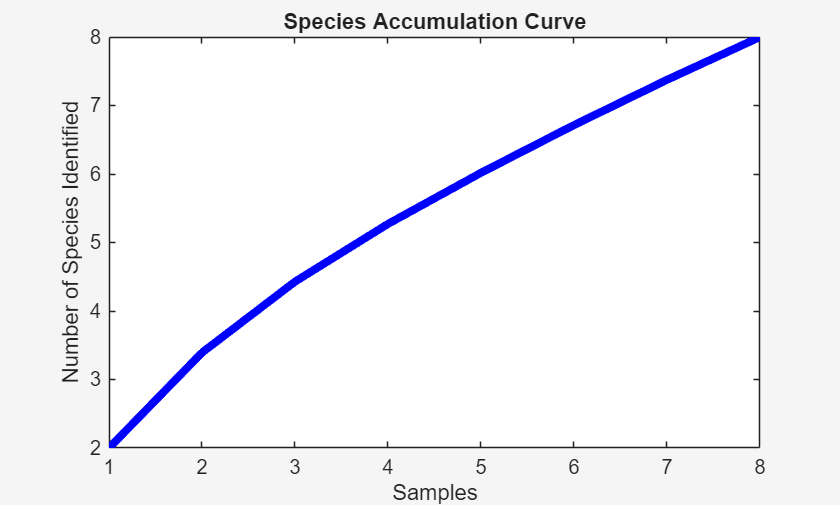


fig1 = plot(1:8, mean_upstream_num_new_spec_perms, 'b', 'LineWidth', 4);
title("Species Accumulation Curve");
ylabel("Number of Species Identified");
xlabel("Samples");
theme("light");
fig.Position(3:4) = [550, 400];
saveas(fig1, "upstream_spec_acc.png");

## DOWNSTREAM


downstream_abundance_data = readtable("downstream_data.csv");

downstream_spec_data = table2array(downstream_abundance_data);
downstream_spec_data(downstream_spec_data > 0) = 1;

num_new_spec_downstream = num_new_spec(downstream_spec_data);

downstream_perm_array = 1:width(downstream_abundance_data);
downstream_permutation_options = perms(downstream_perm_array);
downstream_num_new_spec_perms = num_new_spec_perms(downstream_spec_data, downstream_permutation_options);
mean_downstream_num_new_spec_perms = mean(downstream_num_new_spec_perms)

mean_downstream_num_new_spec_perms =     3.0000    4.7143    5.7143    6.3571    6.8393    7.2500    7.6250    8.0000


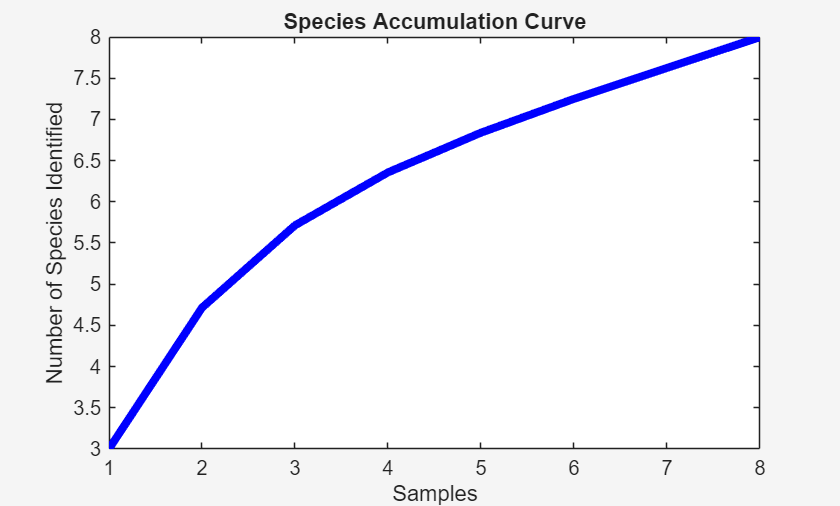


fig2 = plot(1:8, mean_downstream_num_new_spec_perms, 'b', 'LineWidth', 4);
title("Species Accumulation Curve");
ylabel("Number of Species Identified");
xlabel("Samples");
theme("light");
fig.Position(3:4) = [550, 400];
saveas(fig2, "downstream_spec_acc.png");

## PLOT BOTH

domain = 0:8;
domain_extended = 1:15;
mean_upstream_num_new_spec_perms = [0 mean(upstream_num_new_spec_perms)];
mean_downstream_num_new_spec_perms = [0 mean(downstream_num_new_spec_perms)];

%find power fits
fit_domain = (1:8)';
upstream_fit = fit(fit_domain, mean(upstream_num_new_spec_perms)', 'power2');
upstream_fit_a = 3.276;
upstream_fit_b = 0.4982;
upstream_fit_c = -1.259;
upstream_trend = upstream_fit_a .* domain_extended .^ (upstream_fit_b) + upstream_fit_c;
downstream_fit = fit(fit_domain, mean(downstream_num_new_spec_perms)', 'power2');
downstream_fit_a = 49.97;
downstream_fit_b = 0.04661;
downstream_fit_c = -47.09;
downstream_trend = downstream_fit_a .* domain_extended .^ (downstream_fit_b) + downstream_fit_c;

%find exponential fits
extended_fit_domain = (0:8)';
fitfun_exp_start = [-5 -1 10];
fitfun_exp = fittype( @(a,b,c,x) a.*exp(b.*x)+c);
upstream_fit_exp = fit(extended_fit_domain, [0 mean(upstream_num_new_spec_perms)]', fitfun_exp, 'Startpoint', fitfun_exp_start);
downstream_fit_exp = fit(extended_fit_domain, [0 mean(downstream_num_new_spec_perms)]', fitfun_exp, 'Startpoint', fitfun_exp_start);
terminal_upstream = upstream_fit_exp(1000)

terminal_upstream = 10.0581

terminal_downstream = downstream_fit_exp(1000)

terminal_downstream = 8.0157

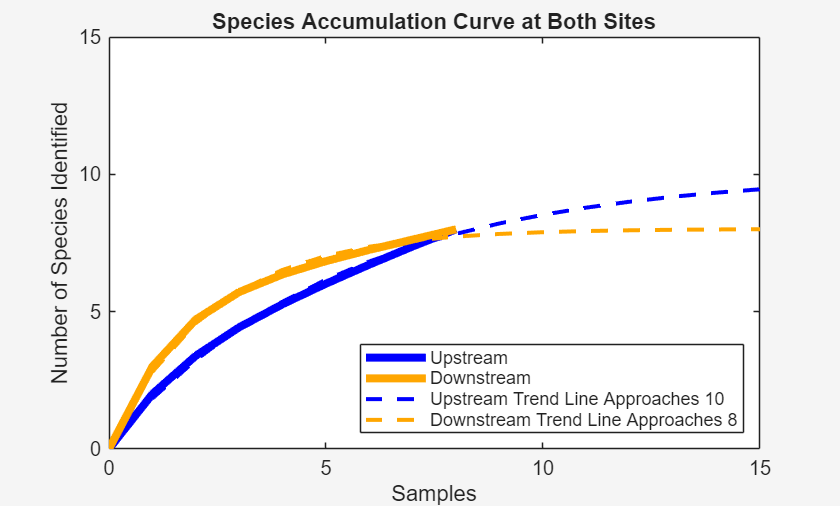


fig3 = plot(domain, mean_upstream_num_new_spec_perms, 'b', 'LineWidth', 4);
hold on;
plot(domain, mean_downstream_num_new_spec_perms, 'Color', [1, 0.65, 0], 'LineWidth', 4);
plot(domain_extended, upstream_fit_exp(domain_extended), 'b', 'LineStyle', '--', 'LineWidth', 2);
plot(domain_extended, downstream_fit_exp(domain_extended), 'Color', [1, 0.65, 0], 'LineStyle', '--', 'LineWidth', 2);
title("Species Accumulation Curve at Both Sites");
legend('Upstream', 'Downstream', 'Upstream Trend Line Approaches 10', 'Downstream Trend Line Approaches 8', 'Location', 'southeast');
ylabel("Number of Species Identified");
xlabel("Samples");
ylim([0 15]);
theme("light");
fig.Position(3:4) = [1000, 800];
saveas(fig3, "spec_acc_linear.png");